% Modelo de energía cartesiano 3GDL
% Erik García Cruz A01732440


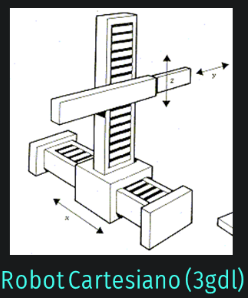


%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
%syms th1(t) th2(t) th3(t)  t   %Angulos de cada articulación
syms l1(t) l2(t) l3(t)  t   %desplazamientos de cada articulación
syms l1p(t) l2p(t) l3p(t)   %Velocidades de cada articulación
syms l1pp(t) l2pp(t) l3pp(t) %Aceleraciones de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3  %Masas y matrices de Inercia
syms logc1 logc2 logc3 % log1 log2 log3 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
  Q= [l1; l2; l3];
 %disp('Coordenadas generalizadas');
 %pretty (Q);
 
 %Creamos el vector de velocidades articulares
  Qp= [l1p; l2p; l3p];
 %disp('Velocidades generalizadas');
 %pretty (Qp);
 %Creamos el vector de aceleraciones articulares
  Qpp= [l1pp; l2pp; l3pp];
 %disp('Aceleraciones generalizadas');
 %pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º en x
R(:,:,1)=        [0 0 1;  %y +90
                  0 1 0;
                 -1 0 0];

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0;0;l2];
%Matriz de rotación de la junta 2 respecto a 1...-90y
    R(:,:,2)=   [1  0  0;  %x +90
                 0  0 -1;
                 0  1  0];
    
%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0; l3];
%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=   [1 0 0;
             0 1 0;     
             0 0 1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%CALCULAMOS LAS VELOCIDADES PARA CADA ESLABÓN%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 3  %%%%%%%%%%

%Calculamos el jacobiano lineal de forma analítica
Jv_a3(:,GDL)=PO(:,:,GDL);
Jw_a3(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a3(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a3(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a3(:,k)= RO(:,3,k-1);
        catch
            Jv_a3(:,k)=[0,0,1];
        end
            Jw_a3(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a3= simplify (Jv_a3);
Jw_a3= simplify (Jw_a3);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac3= [Jv_a3;
      Jw_a3];
Jacobiano3= simplify(Jac3);
 pretty(Jacobiano3);

/ 0, 1,  0 \
|          |
| 0, 0, -1 |
|          |
| 1, 0,  0 |
|          |
| 0, 0,  0 |
|          |
| 0, 0,  0 |
|          |
\ 0, 0,  0 /




%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3


V3=simplify (Jv_a3*Qp);
pretty(V3)

/  l2p(t) \
|         |
| -l3p(t) |
|         |
\  l1p(t) /




 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 3


W3=simplify (Jw_a3*Qp);
pretty(W3)

/ 0 \
|   |
| 0 |
|   |
\ 0 /





%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 2  %%%%%%%%%%

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a2(:,GDL-1)=PO(:,:,GDL-1);
Jw_a2(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
 pretty(Jacobiano2);

/ 0, 1 \
|      |
| 0, 0 |
|      |
| 1, 0 |
|      |
| 0, 0 |
|      |
| 0, 0 |
|      |
\ 0, 0 /




%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2


Qp=Qp(t);
V2=simplify (Jv_a2*Qp(1:2));  
pretty(V2)

/ l2p(t) \
|        |
|    0   |
|        |
\ l1p(t) /



 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2


W2=simplify (Jw_a2*Qp(1:2));
pretty(W2)

/ 0 \
|   |
| 0 |
|   |
\ 0 /






%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 1  %%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-2)=PO(:,:,GDL-2);
Jw_a1(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
 pretty(Jacobiano1);

/ 0 \
|   |
| 0 |
|   |
| 1 |
|   |
| 0 |
|   |
| 0 |
|   |
\ 0 /




%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 1
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


V1=simplify (Jv_a1*Qp(1:1));
pretty(V1)

/    0   \
|        |
|    0   |
|        |
\ l1p(t) /



 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1:1));
pretty(W1)

/ 0 \
|   |
| 0 |
|   |
\ 0 /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, logc1);%La función subs sustituye log1 por logc1 en 
 P12=subs(P(:,:,2), l2, logc2); %la expresión P(:,:,1)/2
 P23=subs(P(:,:,3), l3, logc3);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

%Función de energía cinética

%Calculamos la energía cinética para cada uno de los eslabones%%%%%%%%%%

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

        2 __
|l1p(t)|  m1
------------
      2





%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2);

__          2           2
m2 (|l1p(t)|  + |l2p(t)| )
--------------------------
             2




%Eslabón 3
V3_Total= V3+cross(W3,P23);
K3= (1/2*m3*(V3_Total))'*((V3_Total)) + (1/2*W3)'*(I3*W3);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K3= simplify (K3);
pretty (K3);

__          2           2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )
--------------------------------------
                   2






K_Total= simplify (K1+K2+K3);
disp('Energía Cinética Total');

Energía Cinética Total


pretty (K_Total);

__          2           2           2            2 __   __          2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )   |l1p(t)|  m1   m2 (|l1p(t)|  + |l2p(t)| )
-------------------------------------- + ------------ + --------------------------
                   2                           2                     2




%Energia Potencial  U=mgh

%Obtenemos las alturas respecto a la gravedad
 h1= P01(3); %Tomo la altura paralela al eje z
 h2= P12(3); %Tomo la altura paralela al eje z
 h3= P23(3); %Tomo la altura paralela al eje z

 U1=m1*g*h1

$$U1 = g\,{\mathrm{logc}}_{1}\,m_{1}$$

 U2=m2*g*h2

$$U2 = g\,{\mathrm{logc}}_{2}\,m_{2}$$

 U3=m3*g*h3

$$U3 = g\,{\mathrm{logc}}_{3}\,m_{3}$$


 %Calculamos la energía potencial total
 U_Total= U1 + U2 +U3;

 %Obtenemos el Lagrangiano
 disp('Lagrangiano');

Lagrangiano


 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

__          2           2           2            2 __   __          2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )   |l1p(t)|  m1   m2 (|l1p(t)|  + |l2p(t)| )
-------------------------------------- + ------------ + -------------------------- - g logc1 m1 - g logc2 m2 - g logc3 m3
                   2                           2                     2




%Modelo de Energía
disp('Modelo de Energía');

Modelo de Energía


 H= simplify (K_Total+U_Total);
  pretty (H)

__          2           2           2            2 __   __          2           2
m3 (|l1p(t)|  + |l2p(t)|  + |l3p(t)| )   |l1p(t)|  m1   m2 (|l1p(t)|  + |l2p(t)| )
-------------------------------------- + ------------ + -------------------------- + g logc1 m1 + g logc2 m2 + g logc3 m3
                   2                           2                     2

